%clc
clear all
close all

## Parameters

%AT/PT con polynomial 1.7
%40 weeks con gaussian 1.7
Kernel = 'polynomial';
KernelScale = 1.7; 
Direction = 'forward'; %for sequential feature selection

## LOAD DATA

%% SPECIFY THE FOLDER WITH THE DATA !
addpath("/Users/lucagarello/Desktop/Dataset"); 
[Dataset] = load_dataset('AT.csv','PT.csv'); %1 if you want to detect outliers
%[Dataset2] = load_dataset('40NEG(jan).csv','40POS(jan).csv');


%Dataset = [Dataset ; Dataset2];

%Dataset = find_outliers(Dataset,'gesd',0); %put 1 if you want to plot the outliers 


% 40 weeks OUTLIERS REMOVAL
% Dataset(7,:) = [];
% Dataset(16,:) = [];
% Dataset(26+30,:) = [];

% AT/PT OUTLIERS REMOVAL
Dataset(7,:) = [];
Dataset(15,:) = [];
%writetable(Dataset,"AT-PT.csv") %if you need the data used 

## FEATURES SELECTION

Split Dataset into DATA + LABELS

Data = Dataset{:,1:end-1}; % Parameters
Labels = Dataset{:,end}; % Labels

Sequential feature selection:

if false
    c = cvpartition(Labels,'LeaveOut');
    opts = statset('display','iter');
  
    classf = @(train_data,train_labels,test_data,test_labels) ...
            sum(predict(fitcsvm(train_data,train_labels,'KernelFunction', Kernel, ...
            'PolynomialOrder', [], ...
            'KernelScale', KernelScale, ... 
            'BoxConstraint', 1, ...
            'Standardize', true, 'ClassNames', categorical({'NEG'; 'POS'})), test_data) ~= test_labels); 
    [fs,history] = sequentialfs(classf,Data,Labels,'cv',c,'options',opts,'direction',Direction);
end

Dimensionality reduction:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 40 Weeks feature list
%fs = [1   0   0   0   0   1   0   1   0   0   1   0   0   0   0   0   0   0 ];

% AT/PT feature list
 fs = [ 0   0   0   0   0   1   0   1   0   1   1   1   0   1   0   1   1   0 ];

% All
%fs = [ 1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 ];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

fs = logical(fs);

fprintf('Sono state selezionate le features:');

Sono state selezionate le features:

Dataset(1,fs)

ans = 1×8 table
    JerkFeetCorrelation    skew_hands    Area_Nose    Area_Hands    Area_Feet    AreaStd_Hands    Periodicity_Nose    Periodicity_Hands
    ___________________    __________    _________    __________    _________    _____________    ________________    _________________

         0.057639            30.992       1.9263        33.557       21.879         6.8766            0.001985            0.0043287    



Dataset.Properties.VariableNames

ans = 1×19 cell array
    {'VelHandsCorrelation'}    {'AccHandsCorrelation'}    {'JerkHandsCorrelation'}    {'VelFeetCorrelation'}    {'AccFeetCorrelation'}    {'JerkFeetCorrelation'}    {'skew_Nose'}    {'skew_hands'}    {'skew_feet'}    {'Area_Nose'}    {'Area_Hands'}    {'Area_Feet'}    {'AreaStd_Nose'}    {'AreaStd_Hands'}    {'AreaStd_Feet'}    {'Periodicity_Nose'}    {'Periodicity_Hands'}    {'Periodicity_Feet'}    {'Labels'}


Dataset =  [ Dataset(:,fs) Labels]; 

## TRAINING

trainedClassifier = struct with fields:
    RequiredVariables: {31×1 cell}


Failed prediction of ITEM number 27


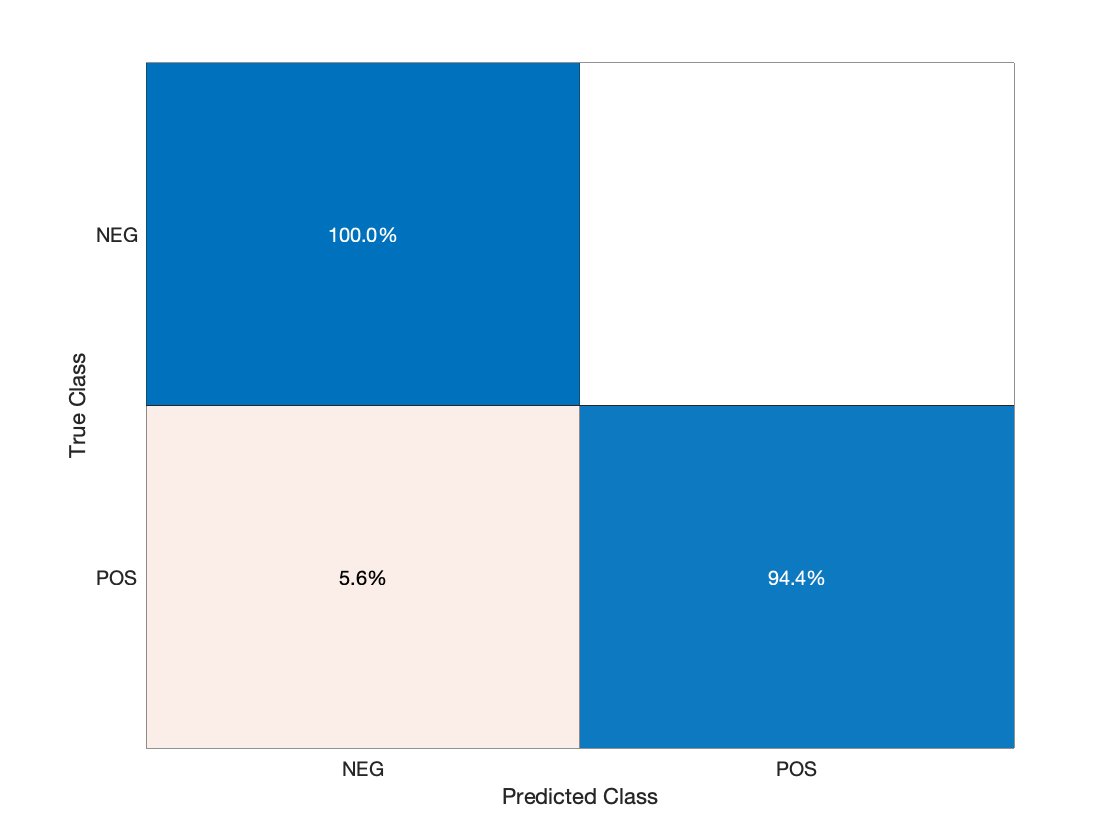

AUC = 0.9573

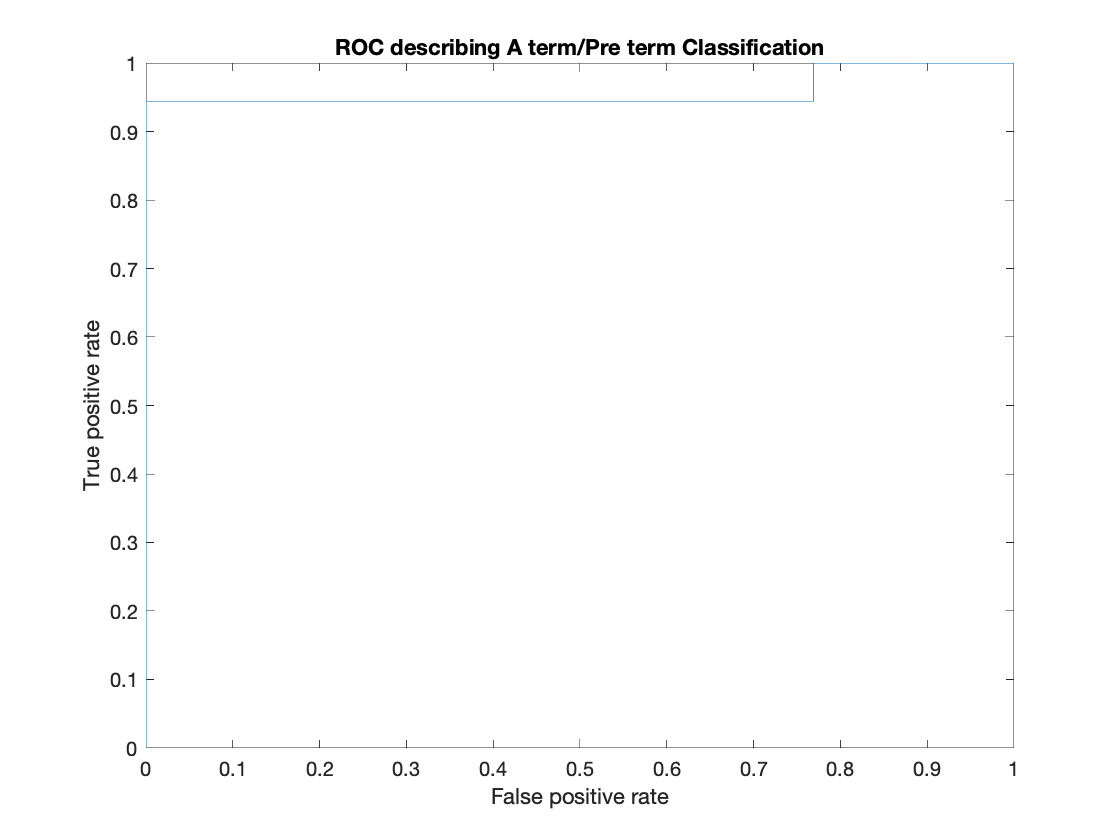

[trainedClassifier, validationAccuracy] = trainClassifier(Dataset,Kernel,KernelScale);

fprintf('The Trainig accuracy is %.1f%% \n',validationAccuracy*100);

The Trainig accuracy is 96.8% 
